# **Programación en Matlab**

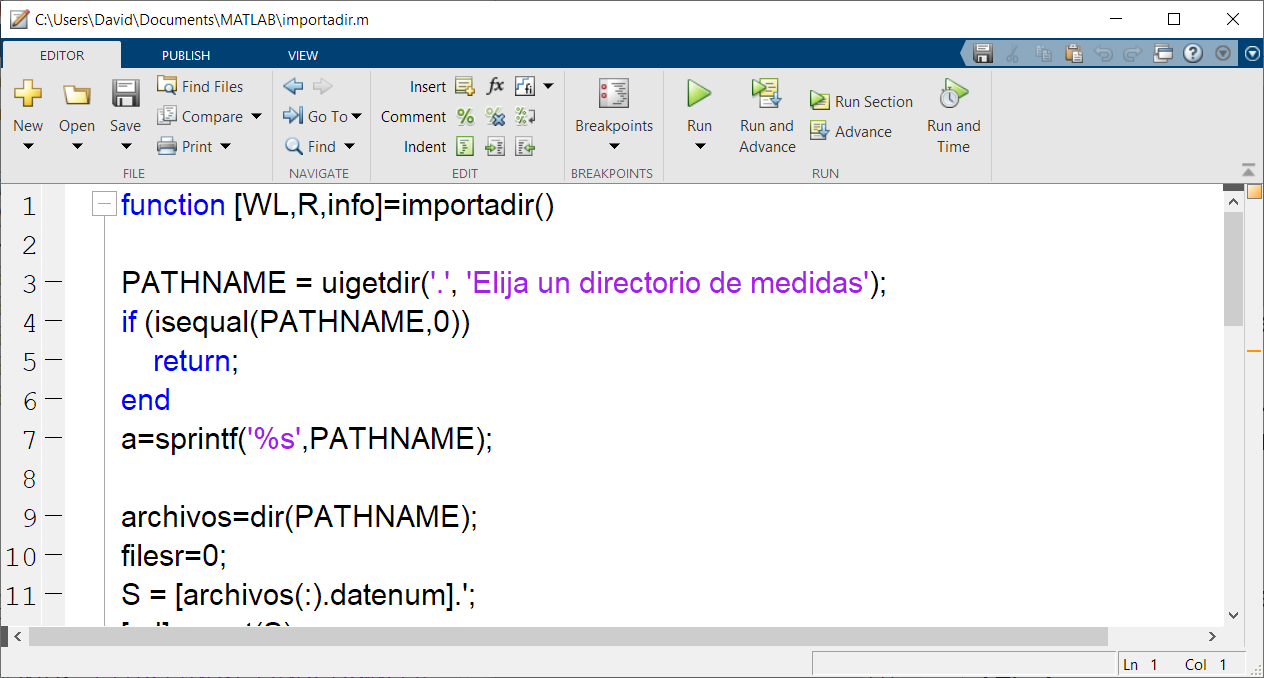

## **Introducción**

En Matlab, los programas se guardan en ficheros con extensión .m

Podemos distinguir dos tipos de programas, los scripts y las funciones.

## **Scripts**

Los *scripts* contienen un conjunto de comandos que se ejecutan sucesivamente. No aceptan argumentos de entrada ni devuelven argumentos de salida y operan sobre datos en el área de trabajo.

Hasta ahora hemos trabajado con *Live scripts*, que son scripts con una capacidad de depuración y edición avanzada, permitiendo que la salida se muestre en el mismo documento.

Cualquier *script* o función se puede guardar como *Live Script* o *Live Function* (.mlx). 

% Dentro de un fichero .m puedes incluir comentarios 
% Para ello debes introducir un %

velocidad = 100;   
tiempo = 1:50;     
velocidadms = velocidad/3.6;
posicion = velocidadms*tiempo

posicion = 	1.0e+03 *

    0.0278    0.0556    0.0833    0.1111    0.1389    0.1667    0.1944    0.2222    0.2500    0.2778    0.3056    0.3333    0.3611    0.3889    0.4167    0.4444    0.4722    0.5000    0.5278    0.5556    0.5833    0.6111    0.6389    0.6667    0.6944    0.7222    0.7500    0.7778    0.8056    0.8333    0.8611    0.8889    0.9167    0.9444    0.9722    1.0000    1.0278    1.0556    1.0833    1.1111    1.1389    1.1667    1.1944    1.2222    1.2500    1.2778    1.3056    1.3333    1.3611    1.3889


Para ejecutar un script o una función debemos introducir su nombre desde la línea de comandos o podemos pulsar el botón *Run*.

## Funciones

Son ficheros con una estructura especial. Con carácter general, una función recibe unos datos de entrada, ejecuta unas órdenes y produce unos datos de salida. Una función tendrá la siguiente estructura:

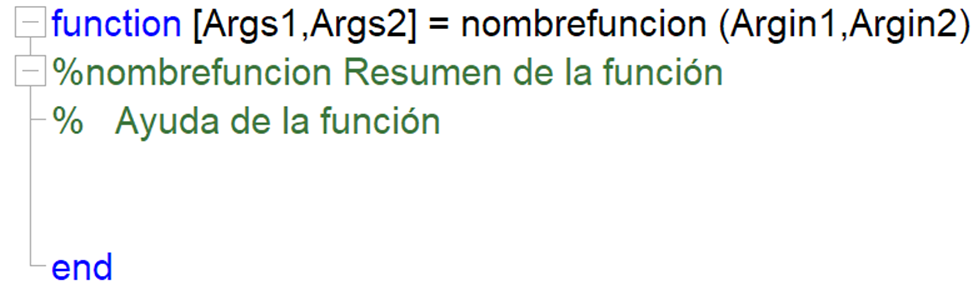

Para llamar a una función escribimos su nombre y los argumentos de entrada y salida como con cualquier otra función de MATLAB. 

>> v = 100;

>> t = 50;

>> Distanciarecorrida = calcularDistancia(v, t);

Se puede obtener el código de una función a través del comando *type *y la ayuda a través del comando* help.*

## Variables locales y globales

Las variables declaradas dentro de una función son variables locales (sólo estarán disponibles dentro de la función). Una alternativa es declarar variables globales. 

global x;

Al declara una variable como global, estará disponible para cualquier función.

## **Funciones anónimas**

Se pueden crear funciones simples de manera mucho más rápida mediante el uso de las funciones anónimas.

Las funciones anónimas no se guardan en un archivo y se asocian a una variable de tipo *function handle*.

Solo permiten tener una instrucción. En la definición de estas funciones el carácter @ indica la creación del *function handle*. Si tuviera parámetros de entrada se especifican entre los paréntesis y separados por comas.  

areaCirculo = @(r) pi*r^2;
A1 = areaCirculo(3)

A1 = 28.2743

area = @(x,r) pi*x/360*r^2;
A2 = area(100,2)

A2 = 3.4907

## **Funciones locales**

Un archivo .m puede contener más de una función. En un archivo de función, la primera función del archivo se llama la **función principal** (visible desde otros archivos o desde la línea de comandos). Las funciones adicionales dentro del archivo se llaman **funciones locales** (sólo son visibles para otras funciones del mismo archivo). 

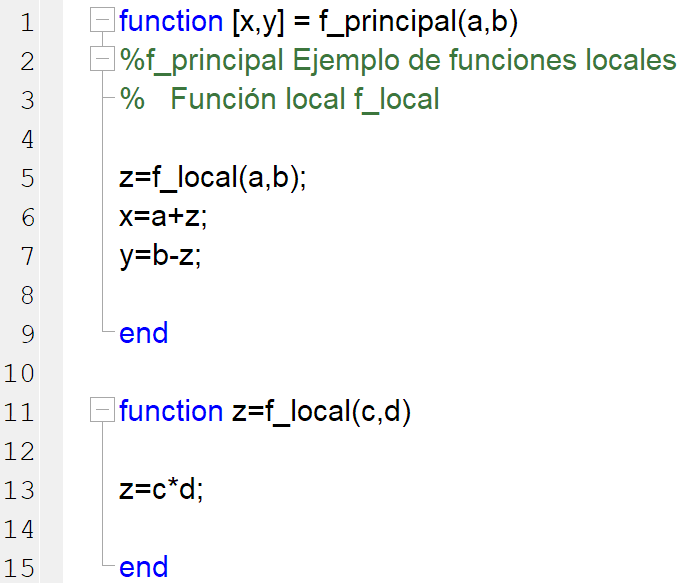

## **Funciones anidadas**

Una función anidada es una función que está completamente contenida dentro de una función principal. La mayor diferencia respecto a las funciones locales es que pueden acceder y modificar variables definidas en sus funciones primarias.

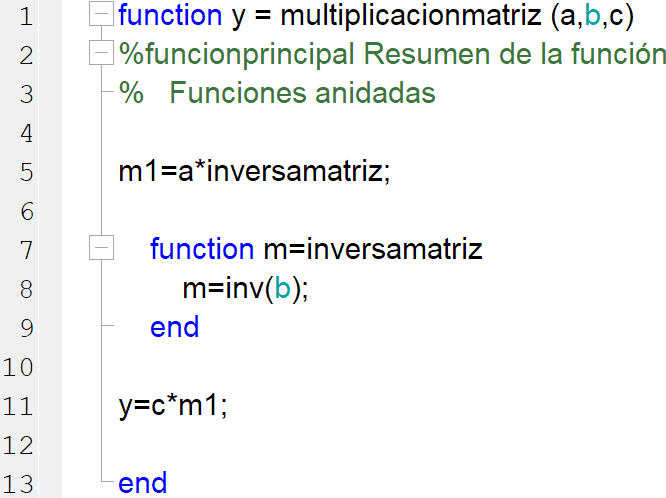

En el ejemplo anterior, el parámetro de entrada b es accesible desde la función anidada sin necesidad de pasarla como argumento de entrada a la función anidada. Note que el color por defecto de la variable cambia para indicar que el ámbito de la variable abarca más de una función.

## **Sentencias condicionales**

Las instrucciones condicionales permiten seleccionar en tiempo de ejecución el bloque de código que se ejecutará. Las instrucciones condicionales más usadas son el bloque *if* y el bloque *switch*.

Para ejecutar sentencias condicionales se requiere conocer algunos de las siguientes estructuras:

- **Operadores relacionales:** *>, >=, <, <=, ==, ~=*.

-  **Operadores lógicos:** *&* (AND), *|* (OR), *~ *(NOT), *xor* (OR exclusiva). Usando la expresión doble && o ||, sólo se evalúa si la primera parte cumple la condición. 

- **Funciones lógicas:** *any* (devuelve verdadero si algún valor cumple la condición), *all* (devuelve verdadero si todos los valores cumplen la condición), find (devuelve el índice de los elementos que cumplen la condición. 

array = randi([0 20], 1, 10)

array =     12    11    19     6    15    15     7    11     1     1


all(array~=0)

ans = logical
   1


any (array==3 | array == 7)

ans = logical
   1


find(array>8 & array<15)

ans =      1     2     8


### **Bloque if**

Se ejecuta un bloque de instruciones si la sentencia es verdadera. Se puede incluir un bloque *elseif* (para añadir una nueva condición) y *else* (para ejecutar si no se cumplen las expresiones anteriores). La estructura es:

                ***if**** expresion*

*                    bloque1*

                ***elseif**** expresion*

*                    bloque2*

                ***else***

*                    bloque3*

                ***end***

x = randi([1 100])

x = 54

if (rem(x,2) == 0)
    disp('x es un número par')
else
    disp('x es un número impar')
end

x es un número par


### **Bloque Switch**

Se utiliza para seleccionar uno de varios bloques de instrucciones. Su estructura es: 

            ***switch**** expresión*

               ***case**** caso1*

*                  bloque1*

               ***case**** caso2*

*                  bloque2*

               ***otherwise***

*                  bloqueAlternativo*

            ***end***

% n = input('Introduce un numero: ');
% 
% switch n
%     case {-1,-2}
%         disp('1 o 2 negativo')
%     case 0
%         disp('cero')
%     case {1,2}
%         disp('1 o 2 positivo')
%     otherwise
%         disp('otro valor')
% end

## Bucles

Las instrucciones condicionales permiten ejecutar varias veces un bloque de código. Hay dos tipos de bucles fundamentales que son el bucle *for* y el bucle *while*.

### Bucle for

Repite las instrucciones un número determinado de veces. La sintaxis es:

***                for**** indice = valores*

*                   bloque1*

***                end***

donde valores puede ser un vector o serie. Veamos un ejemplo:

A = ones(1,20);
for v = 3:20
    A(v) = A(v-1)+A(v-2);
end
A

A =            1           1           2           3           5           8          13          21          34          55          89         144         233         377         610         987        1597        2584        4181        6765


### Bucle while

Repite una secuencia mientras se cumple una condición.

                ***while**** expresion*

*                    bloque1*

                ***end***

B = 0

B = 0

while (B<10 && B>-10)
    B = B + randi([-1 2])
end

B = 2

B = 4

B = 3

B = 4

B = 4

B = 3

B = 3

B = 2

B = 4

B = 4

B = 5

B = 4

B = 5

B = 5

B = 6

B = 7

B = 8

B = 8

B = 7

B = 6

B = 8

B = 7

B = 9

B = 10

### **Otros comandos de control**

Podemos usar *break* (para interrumpir un bucle) o *continue* (para pasar al siguiente elemento).

% while (true)
%     A = input('Introduce un número del 1 al 5: ');
%     B = randi([1 5])
%     if (A==B)
%         break;
%     end
% end


% for i =1:5
%     numero = input('Pulsa 1: ');
%     if (numero==1)
%         continue
%     end
%     %Esto no se ejecuta si has pulsado el 1
%     r = i+i
% end

## Gestión de argumentos

Podemos utilizar las siguientes funciones para gestionar los argumentos de entrada o salida en una función. 

        *nargin/nargout*: Devuelven el número de argumentos de entrada/salida.

                *varargin/varargout*: Lista de argumentos de entrada/salida.

                *narginchk/nargoutchk*: Verifica el número de argumentos de entrada/salida. 

## 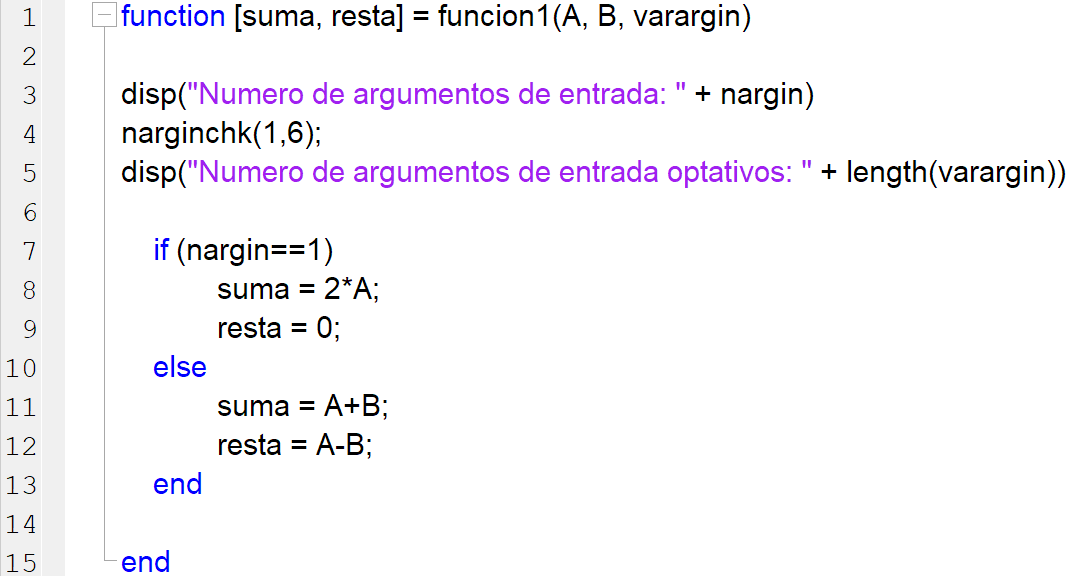

## Manejo de excepciones

Podemos utilizar el bloque *try/catch* para gestionar las excepciones. Si aparece un error dentro del bloque *try*, se ejecutará el boque *catch*.

***try***

*   statements*

***catch**** exception*

*   statements*

***end***

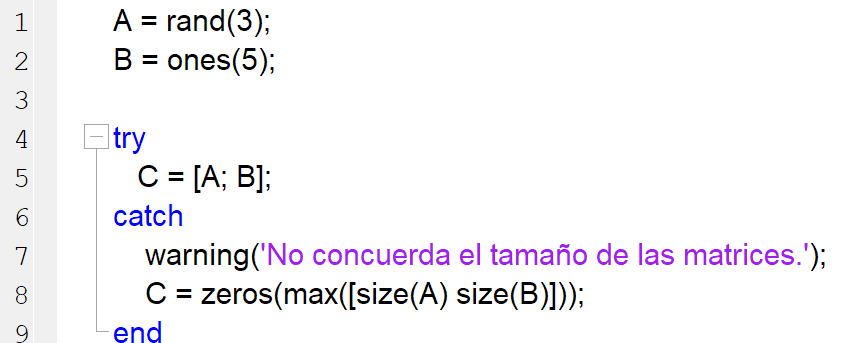

## Ejercicios

### Ejercicio 1

Considere un cono. Escriba una **función** de MATLAB que calcule y devuelva el volumen del cono dados el radio ***r ***y la altura ***h*** del cono como argumentos de entrada.


$$V=\frac{1}{3}\pi r^2 h$$


En primer lugar, la función deberá comprobar que el tanto el radio como la altura son escalares positivos.


type calculo_volumen_cono.m

function [volumen_cono] = calculo_volumen_cono(r,h)

    try
        volumen_cono = (1/3)*pi*r*r*h;
        
        if (isscalar(r) && isscalar(h)) && (r>0 && h>0)
            volumen_cono = (1/3)*pi*r*r*h;
        else
            warning("El valor del radio y la altura deben ser escalares positivo");
            volumen_cono = "No es posible calcularlo";
        end
        
    catch 
        warning("El valor ""r"" o ""h"" NO es escalar ");
        volumen_cono = "No es posible calcularlo";
        
    end


end



r = 25;
h = 10;


% Caso en el cual r es un número
volumen_cono = calculo_volumen_cono(r,h)

volumen_cono = 6.5450e+03


% Caso en el cual r es menor a 0
r = -5

r = -5

volumen_cono = calculo_volumen_cono(r,h)

volumen_cono = "No es posible calcularlo"


% Caso en el cual r no es un número
volumen_cono = calculo_volumen_cono("r",h)

volumen_cono = "No es posible calcularlo"

### Ejercicio 2

Escriba una función que tenga como entrada dos valores y devuelva una matriz cuadrada. El primer argumento de entrada indicará el tamaño de la matriz. El segundo argumento ***x***, servirá para calcular los elementos de la matriz tal que: 


$$\left\lbrack \begin{array}{ccccccc}
1 & x & x^2  & \cdots  & \cdots  & x^{n-2}  & x^{n-1} \\
x & x^2  & \cdots  & \ddots  & x^{n-2}  & x^{n-1}  & x^{n-2} \\
x^2  & \cdots  & \ddots  & x^{n-2}  & x^{n-1}  & x^{n-2}  & \vdots \\
\vdots  & \ddots  & x^{n-2}  & x^{n-1}  & x^{n-2}  & \ddots  & \vdots \\
\vdots  & x^{n-2}  & x^{n-1}  & x^{n-2}  & \ddots  & \cdots  & x^2 \\
x^{n-2}  & x^{n-1}  & x^{n-2}  & \ddots  & \cdots  & x^2  & x\\
x^{n-1}  & x^{n-2}  & \cdots  & \cdots  & x^2  & x & 1
\end{array}\right\rbrack$$



type matriz_cuadrada.m

function [matriz_cuadrada_resultante] = matriz_cuadrada(tamano,argumento_x)
    try

        if tamano<0
            tamano=tamano*-1;
            warning("El tamaño es negativo, se ha pasdo a positivo");
        end
        matriz = zeros(tamano);
        vector = zeros(1,argumento_x);
        for i=1:(2*size(matriz,1)-1)
            if i <=tamano
                vector(i) = argumento_x^(i-1);
            else
                vector(i) = vector(i-1)/argumento_x;
            end
        end

        for i=1:size(matriz,1)
            matriz(i,:)=vector(i:(i+(tamano-1)));
        end
        matriz_cuadrada_resultante = matriz;
    catch
        warning("El tamaño de la función y el argumento deben ser escalares positivos");
        matriz_cuadrada_resultante = "No es posible calcularlo";
    end
end




% Casos de funcionamiento
salida_1 = matriz_cuadrada(3,5)

salida_1 =      1     5    25
     5    25     5
    25     5     1



salida_2 = matriz_cuadrada(6,2)

salida_2 =      1     2     4     8    16    32
     2     4     8    16    32    16
     4     8    16    32    16     8
     8    16    32    16     8     4
    16    32    16     8     4     2
    32    16     8     4     2     1



salida_3 = matriz_cuadrada(5,5)

salida_3 =      1     5    25   125   625
     5    25   125   625   125
    25   125   625   125    25
   125   625   125    25     5
   625   125    25     5     1



salida_4 = matriz_cuadrada(3,8)

salida_4 =      1     8    64
     8    64     8
    64     8     1



% Caso con argumento negativo
salida_5 = matriz_cuadrada(8,-2)

salida_5 =      1    -2     4    -8    16   -32    64  -128
    -2     4    -8    16   -32    64  -128    64
     4    -8    16   -32    64  -128    64   -32
    -8    16   -32    64  -128    64   -32    16
    16   -32    64  -128    64   -32    16    -8
   -32    64  -128    64   -32    16    -8     4
    64  -128    64   -32    16    -8     4    -2
  -128    64   -32    16    -8     4    -2     1



% Caso con argumento no escalar
salida_6 = matriz_cuadrada(3,[1,5])

salida_6 = "No es posible calcularlo"


% Caso con tamaño negativo
salida_7 = matriz_cuadrada(-4,5)

salida_7 =      1     5    25   125
     5    25   125    25
    25   125    25     5
   125    25     5     1


### Ejercicio 3

Escriba una función que calcule y dibuje la siguiente función entre 0 y 10:


$$y=\sin \left(2\pi \cdot \textrm{f1}\cdot t+a\right)+\cos \left(2\pi \cdot \textrm{f2}\cdot t+b\right)$$


La función tendrá cuatro parámetros de entrada: f1,f2,a y b. Siendo f1, f2 escalares positivos que representan las frecuencias de las sinusoides y a,b también dos escalares que representan la fase de las señales. *t* representa el tiempo.

La función devolverá el valor de la función (y).

Recuerde añadir las etiquetas a los ejes.


type representacion_funcion.m

function [funcion] = representacion_funcion(f1,f2,a,b)

    t = linspace(0,10,250);

    if (isscalar(f1) && isscalar(f2) && isscalar(a) && isscalar(b))
        if f1>0 && f2>0
            funcion = sin(2*pi*f1*t +a) + cos(2*pi*f2*t+b);
            figure();
            plot(t,funcion);
            title("EJERCICIO 3");xlabel("Tiempo");ylabel("Amplitud");
        else
            warning("El valor de las frecuencias debe ser escalar positivo");
        end
    else
        warning("Las frecuencias y desfases deben ser escalares");
    end
end



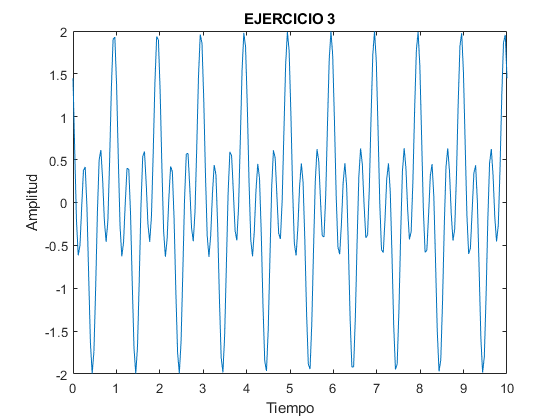

ans =     1.4496    0.5915   -0.2147   -0.6165   -0.5003   -0.0472    0.3738    0.4150   -0.0530   -0.8633   -1.6387   -1.9932   -1.7410   -0.9968   -0.1152    0.5000    0.6114    0.2713   -0.2138   -0.4585   -0.2165    0.4776    1.3213    1.9042    1.9293    1.3736    0.5015   -0.2773   -0.6274   -0.4650    0.0030    0.3994    0.3906   -0.1237   -0.9495   -1.6983   -1.9958   -1.6843   -0.9078   -0.0359    0.5354    0.5942    0.2229   -0.2549   -0.4581   -0.1643    0.5619    1.3978    1.9347    1.8975



% Funcionamiento normal
representacion_funcion(1,3,2,1)


% Caso frecuencias no escalares
representacion_funcion(2,[2,5],5,-6)

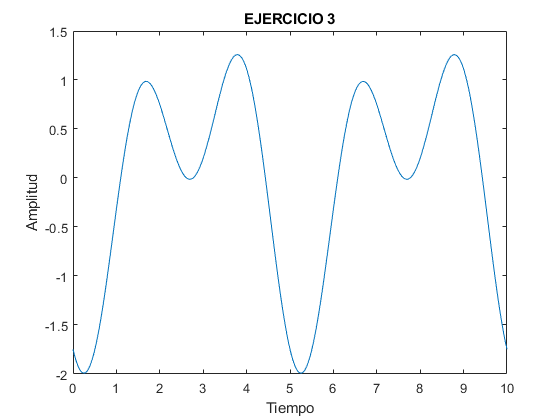

ans =    -1.7484   -1.8188   -1.8777   -1.9248   -1.9596   -1.9819   -1.9916   -1.9885   -1.9728   -1.9447   -1.9044   -1.8523   -1.7890   -1.7149   -1.6308   -1.5375   -1.4358   -1.3265   -1.2106   -1.0893   -0.9634   -0.8341   -0.7024   -0.5696   -0.4366   -0.3046   -0.1746   -0.0477    0.0751    0.1930    0.3050    0.4103    0.5082    0.5981    0.6793    0.7516    0.8144    0.8675    0.9108    0.9442    0.9677    0.9816    0.9859    0.9812    0.9677    0.9461    0.9169    0.8807    0.8384    0.7907



% Funcionamiento normal con fases negativas
representacion_funcion(50,100,-2,-10)


% Caso frecuencias negativas
representacion_funcion(-4,-7,-2,-10)

### Ejercicio 4

Escriba una función *myorder* que ordene un vector de escalares. Esta función tendrá como mínimo un parámetro  de entrada que será el vector. Si se llama a la función con un único parámetro de entrada la función recorrerá el vector y ordenará sus elementos de mayor a menor. Si se llama a la función con dos parámetros de entrada el segundo argumento aceptará una cadena de caracteres cuyo valor puede ser 'ascendente' o 'descendente', y en función de este valor ordenará el vector de menor a mayor o de mayor a menor, respectivamente. En ambos casos la función debe devolver un vector ordenado. Use la función ***sort*** dentro de su función.


type myorder.m

function [vector_ordenado] = myorder(vector,tipo)
    if size(vector,1)==1
        warning("El vector introducido solo tiene un valor");
        vector_ordenado = vector;
    else
        if  nargin == 2
            if tipo == "ascendente"
                  vector_ordenado = sort(vector);

            elseif tipo == "descendente"
                   vector_ordenado = fliplr(sort(vector));   
            end        
        else
                vector_ordenado = sort(vector);  
        end
    end
end



tipo = "ascendente";
vector = [-9,57,50-7,0,6,14,3];
% Funcionamiento con un parámetro
salida = myorder(vector)

salida =     -9    57    43     0     6    14     3



% Funcionamiento con dos parámetros
salida =  myorder(vector,tipo)

salida =     -9    57    43     0     6    14     3



% Caso "descendente"
tipo = "descendente";
salida =  myorder(vector,tipo)

salida =     -9    57    43     0     6    14     3



% Caso vector de un elemento
vector = [5];
salida =  myorder(vector,tipo)

salida = 5


% Caso vector columnas
vector = [1;5;8;7;3;4;2;6;9];
salida =  myorder(vector,tipo)

salida =      1
     2
     3
     4
     5
     6
     7
     8
     9



% Caso vector de tecto
vector = "texto";
salida =  myorder(vector,tipo)

salida = "texto"